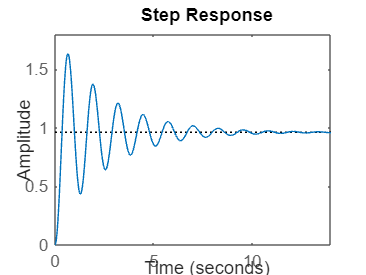

z1 = -5;
p1 = [-1 -2 -2];
dcgain1 = 19.9597;
sys1 = zpk(z1, p1, dcgain1);
sys2 = feedback(sys1, 1, -1);
step(sys2);     % 步階

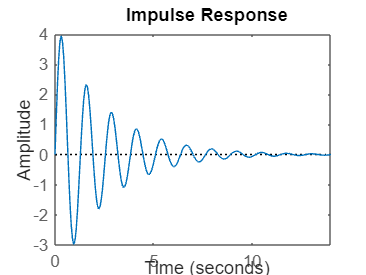

impulse(sys2);  % 脈衝

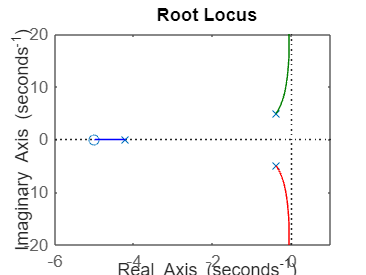

rlocus(sys2);   % 根軌跡圖

根軌跡圖（Root Locus Plot）是控制工程中的一種圖形工具，用於分析線性控制系統的特徵根（或極點）如何隨系統參數變化而變動。通常用來觀察當控制系統中的增益參數變化時，閉環系統的極點如何沿著複數平面上的路徑運動。

根軌跡圖的作用在於，系統的穩定性與極點的位置密切相關，當極點位於複數平面的左半邊（實部為負）時，系統是穩定的；而當極點移到右半邊（實部為正）時，系統變得不穩定。通過繪製根軌跡圖，可以分析增益如何影響系統的穩定性。

#### G

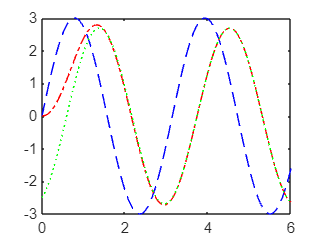

G = tf([1 5], [1 3 4]); % 平台
t = 0 : 0.05 : 6; % 時間設定，0.05自己訂的，看要多細
u = 3 * sin(2 * t);
y = lsim(G, u, t);
% lsim 使用於求 LTI SyStem 的輸出響應，其中 G 為轉移函數，u 為輸入訊號，t 為時間
[mag, phase] = bode(G, 2);
% 將波德圖的大小及相位回傳至自定變數，其中 G 為轉移函數，2 為輸入訊號角頻率
yss = 3 * mag * sin (2 * t + phase * pi / 180);
plot(t, u, 'b--', t, y, 'r-.', t, yss, 'g:');

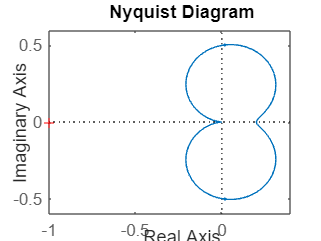

G = tf(5, [1 2 25]);
% figure(1);
nyquist(G); % 需軸上的穩定叫臨界穩定

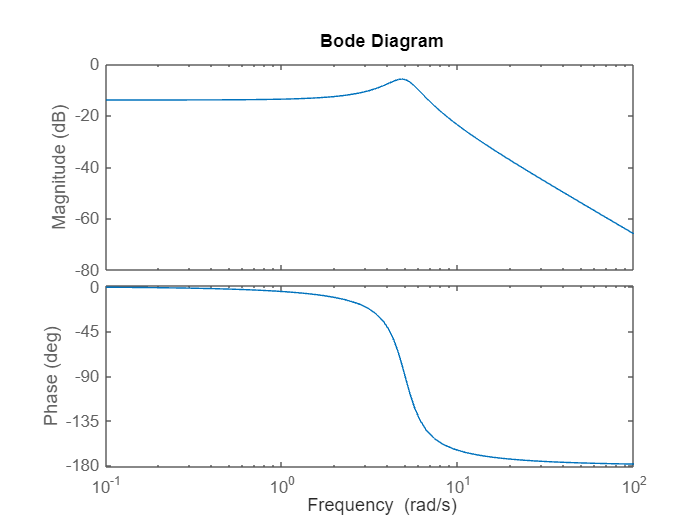

% figure(2);
bode(G)

臨界穩定（Marginal Stability）是控制系統中的一種特殊狀態，表示系統既不穩定也不穩定衰減。在這種情況下，系統的輸出將不會發散（如不穩定系統），但也不會完全收斂到一個穩定的值（如穩定系統）。具體來說，臨界穩定的系統輸出通常會持續振盪，但這些振盪的幅度既不增長也不減少，保持恆定。

% A = [1 -1.5 0.7];
% B = [0 1 0.5];
% C = [1 -1 0.2]; 
